# Experimento 1 - Filtros Adaptativos

**PSI3531 Processamento de Sinais Aplicado**

Bruno Hashimoto (10715628)

Guilherme Fernandes Gonçalves Silva (10297272)

## Eliminação de Interferências

% Definição de Variáveis

M = 2; % coeficientes do filtro adaptativo
N = 1000; % numero de pontos
n = 0:N-1;
phi_v = 2*pi*rand;% (2*pi)*rand(N,1); % U ~ [0, 2pi]
phi_u = phi_v;

s = sqrt(0.01) .* randn(N, 1); % s(n) - ruido branco (0, 0.01)
x = sin(2*pi*n/10 + pi/6 + phi_v')' ; % x(n) - interferencia
u = 5*sin(2*pi*n/10 + phi_u')'; % u(n) - sinal correlacionado com interferencia

d = s + x; % d(n)

**a) **

Calcule a Matrix de autocorrelação R e o vetor de correlação cruzada p entre a entrada e o sinal desejado.

A matriz de autocorrelação é definida por:


$$R = E \{u(n) u^{T}(n)\} = \pmatrix{r_{uu}(0) & r_{uu}(1) \cr r_{uu}(1) & r_{uu}(0)}$$


Cada elemento da matrix pode ser calculado utilizando-se a seguinte fórmula:


$$r_{uu}(k) = E\{u(n)u(n-k)\}$$


Substituindo o sinal u(n), tem-se:


$$r_{uu}(k) = E\{5 sin(\frac{2 \pi n}{10} + \phi_{u}) \cdot 5 sin(\frac{2 \pi (n-k)}{10} + \phi_{u})\} \\


r_{uu}(k) = E\{25 sin(\frac{2 \pi n}{10} + \phi_{u}) \cdot sin(\frac{2 \pi n}{10} - \frac{2 \pi k}{10} + \phi_{u})\}$$


usando a identidade $sin(a)sin(b)=\frac{1}{2}cos(a-b)-\frac{1}{2}cos(a+b)$, obtém-se:


$$r_{uu}(k) = \frac{25}{2}E\{cos(\frac{2 \pi k}{10}) - cos(\frac{4 \pi n}{10} - \frac{2 \pi k}{10} + 2\phi_{u})\} \\

r_{uu}(k) = \frac{25}{2}\big(cos(\frac{2 \pi k}{10}) - E\{cos(\frac{4 \pi n}{10} - \frac{2 \pi k}{10} + 2\phi_{u})\} \big)$$


Como $\phi_u$ é variável aleatória entre 0 e $2\pi$, tem-se que a esperança $E\big\{cos(\frac{4 \pi n}{10} - \frac{2 \pi k}{10} + 2\phi_{u})\big\} = 0$, a partir da identidade do cosseno da soma.


$$E\big\{cos(\frac{4 \pi n}{10} - \frac{2 \pi k}{10} + 2\phi_{u})\big\} = cos(\frac{4 \pi n}{10} - \frac{2 \pi k}{10})E\{cos(2\phi_u)\} - sin(\frac{4 \pi n}{10} - \frac{2 \pi k}{10})E\{sin(2\phi_u)\} \\

E\{cos(2\phi_u)\} = E\{sin(2\phi_u)\}= 0$$


Portanto, temos que $r_{uu}(k) = \frac{25}{2} cos(\frac{2 \pi k}{10}) 
$, e finalmente a matrix R


$$R = \frac{25}{2}\pmatrix{1 & cos\big(\frac{\pi}{5}\big) \cr cos\big(\frac{\pi}{5}\big) & 1}$$


Para calcular a o vetor p, segue-se o mesmo procedimento com $r_{du}(k) = E\{d(n)u(n-k)\}$:


$$r_{du}(k)  =  E\big\{sin(\frac{2 \pi n}{10} + \frac{\pi}{6} + \phi_{u}) \cdot 5 sin(\frac{2 \pi n}{10} - \frac{2 \pi k}{10} + \phi_{u}) \big\} \\

r_{du}(k) = \frac{5}{2} E\big\{cos(\frac{2 \pi k}{10} + \frac{\pi}{6}) - cos(\frac{4 \pi n}{10} + \frac{\pi}{6} - \frac{2 \pi k}{10} + 2\phi_{u})\big\} \\

r_{du}(k) = \frac{5}{2}cos(\frac{2 \pi k}{10} + \frac{\pi}{6})$$


Finalmente, tem-se:


$$p = \frac{5}{2}\pmatrix{cos\big(\frac{\pi}{6}\big) \cr cos\big(\frac{\pi}{5}+\frac{\pi}{6}\big)}
$$


O vetor de coeficientes ótimos é obtido por $w_o = R^{-1}p$ e o erro quadrático médio mínimo $J_{min} = \sigma_d^2 - p^Tw_o$, serão calculados a seguir.

A variância de d(n) ($\sigma_d^2$) é dada por $E\{d^2(n) - E\{d(n)\}^2 \}$, em que $E\{d(n)\}=0$, então tem-se que:


$$\sigma_d^2 = E\{x^2(n) + s^2(n) + 2x(n)s(n)\} = E\{x^2(n)\} + E\{s^2(n)\} \\
\sigma_d^2 =  0.5 + 0.01 = 0.51$$


% Matrix autocorrelação R 
R = 12.5 * [1 cos(pi/5); cos(pi/5) 1]

R =    12.5000   10.1127
   10.1127   12.5000


% vetor p de correlação cruzada
p = 2.5*[cos(pi/6);cos(pi/5+pi/6)]

p =     2.1651
    1.0168


% vetor de coeficientes ótimos (wo)
wo = R \ p % inv(R) * p

wo =     0.3108
   -0.1701


% Erro quadrático médio mínimo J_min
var_d = 0.51;
J_min = var_d - p'*wo

J_min = 0.0100

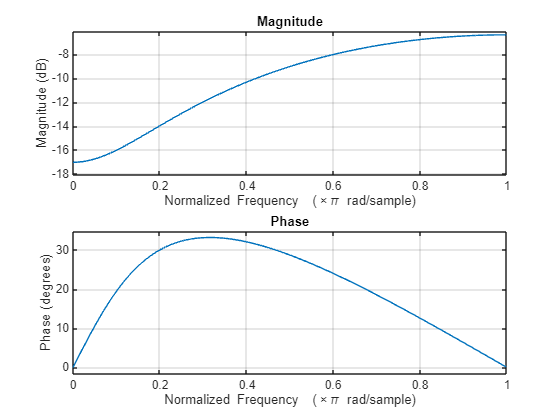

% Resposta em frequência
freqz(wo, 1);

Na frequência da interferência $0.2\pi$ rad/sample, a magnitude do sinal é atenuada em 14dB, o que equivale a uma redução de um quinto do sinal de entrada no filtro, uma vez que $20\text{log}_{10}(0.2) = -14 \text{dB}$. Além da alteração de fase de $30^{o}$. Dessa forma, o filtro corretamente filtra u(n).

**b) **

Os autovalores obtidos da matriz R são:

eigenvalues = eig(R)

eigenvalues =     2.3873
   22.6127


A estabilidade é garantida se o passo de adaptação $\mu$ satisfazer a relação:

fprintf('0 < mu < %f', 2/max(eigenvalues));

0 < mu < 0.088446

**c)**

Os sinais de entrada u(n), erro e(n) e desejado s(n) são mostrados na Figura abaixo. Pode-se observar que o erro é expressivo inicialmente, mas com o decorrer da simulação ele converge para o sinal desejado. Como espeado pelo algorítmo LMS.

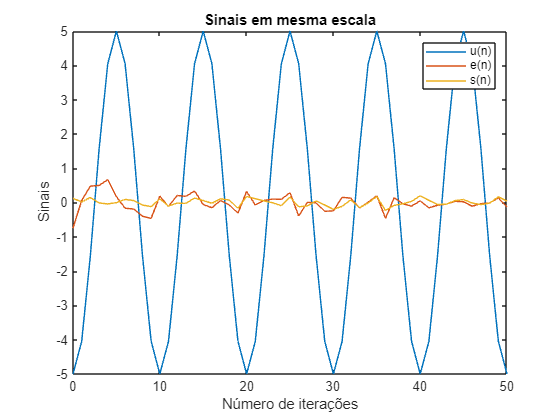

N_iter = 500; % numero de iterações
mu = 0.03; 

% i
[W, erro] = lms(u, d, M, N_iter, mu);
% plotar u e s com indice do numero de iteracoes (?)
plot(0:N_iter-1, u(1:N_iter), 0:N_iter-1, erro, 0:N_iter-1, s(1:N_iter));
legend('u(n)', 'e(n)', 's(n)');
xlim([0, 50]);
title('Sinais em mesma escala');
xlabel('Número de iterações');
ylabel('Sinais');

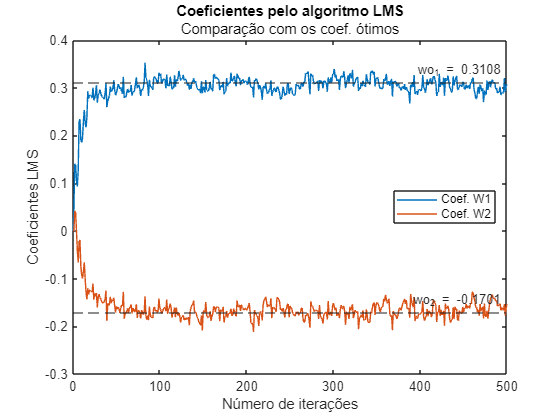

%% ii
plot(0:N_iter, W);
yline(wo, '--', {'wo_1 = 0.3108','wo_2 = -0.1701'});
title('Coeficientes pelo algoritmo LMS');
subtitle('Comparação com os coef. ótimos')
%legend('Adap. Ref: 0,3108', 'Adap. Ref: -0,1701', 'Location','east');
legend('Coef. W1', 'Coef. W2', 'Location', 'east');
xlabel('Número de iterações');
ylabel('Coeficientes LMS');

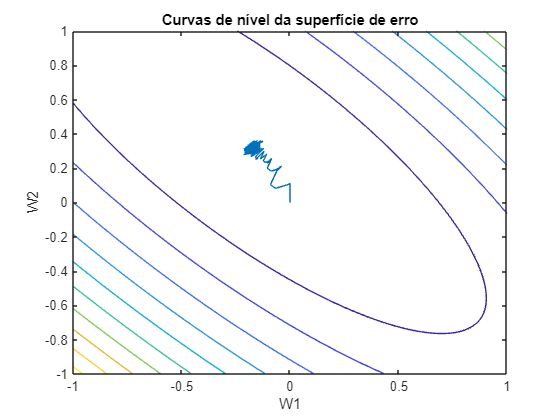

%% iii
W1 = -1:0.01:1;
W2 = W1;
Ncn = length(W1);
for i = 1:Ncn
    for j = 1:Ncn
        Wnc = [W1(i); W1(j)];
        J(i,j) = var_d - 2*Wnc'*p + Wnc'*R*Wnc;
    end
end

figure;
contour(W1, W2, J);
hold on;
plot(W(:,2), W(:,1));
title('Curvas de nível da superfície de erro');
xlabel('W1');
ylabel('W2');

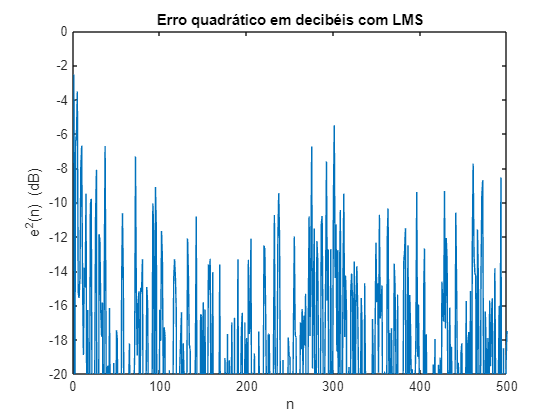

%% iv
[~, erro] = lms(u, d, M, N_iter, mu);
erro_quad_db = 10*log10(erro.*erro);

figure;
plot(1:N_iter, erro_quad_db);
ylim([-20 0]);
ylabel('e^2(n) (dB)');
xlabel('n');
title('Erro quadrático em decibéis com LMS');

**d)** 

O valor teórico máximo de $\mu$, para se obter a convergência do algoritmo LMS, foi de 0.065. No entanto, pode-se observar experimentalmente que para valores maiores de $\mu$, já ocorre a divergência para pelo menos uma das simulações. Como por exemplo, para $\mu$ = 0.07 o gráfico abaixo mostra essa situação de divergência. Como o algoritmo divergiu em pelo menos 1 simulação, considera-se que ele diverge para aquele valor de $\mu$, como é o caso de $\mu=0.069$.

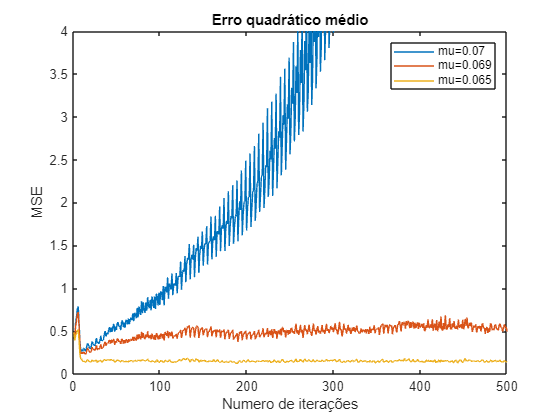

N_monte_carlo = 1000;
erro_med1 = zeros(1,N_iter);
erro_med2 = zeros(1,N_iter);
erro_med3 = zeros(1,N_iter);
mu1 = 0.07;
mu2 = 0.069;
mu3 = 0.065;

for i = 0:N_monte_carlo-1
    phi_u = 2*pi*rand;
    x = sin(2*pi*n/10 + pi/6 + phi_u);
    u = 5*sin(2*pi*n/10 + phi_u);
    s = sqrt(0.01)*randn(1,N);
    d = s + x;
    
    [~, erro1] = lms(u, d, M, N_iter, mu1);
    erro_med1 = erro_med1 + erro1.*erro1;

    [~, erro2] = lms(u, d, M, N_iter, mu2);
    erro_med2 = erro_med2 + erro2.*erro2;

    [~, erro3] = lms(u, d, M, N_iter, mu3);
    erro_med3 = erro_med3 + erro3.*erro3;
end

erro_med1 = erro_med1/N_monte_carlo;
erro_med2 = erro_med2/N_monte_carlo;
erro_med3 = erro_med3/N_monte_carlo;

plot(1:N_iter, erro_med1, 1:N_iter, erro_med2, 1:N_iter, erro_med3);
ylabel('MSE');
xlabel('Numero de iterações');
title('Erro quadrático médio');
legend('mu=0.07', 'mu=0.069', 'mu=0.065');
ylim([0 4]);

e)

%% i
N_monte_carlo = 1000;
mu = 0.03;
erro_med = zeros(1,N_iter);
for i = 1:N_monte_carlo
    phi_u = 2*pi*rand;
    x = sin(2*pi*n/10 + pi/6 + phi_u);
    u = 5*sin(2*pi*n/10 + phi_u);
    s = sqrt(0.01)*randn(1,N);
    d = s + x;

    [W, erro] = lms(u, d, M, N_iter, mu);
    erro_med = erro_med + erro.*erro;
end
mse = erro_med/N_monte_carlo;

%% ii
sigma_v_2 = 0.01; %var(x);
%experimental
emse = mse - J_min;
%teorico
EMSE_teorico = mu*sigma_v_2*trace(R)/(2-mu*trace(R))

EMSE_teorico = 0.0060

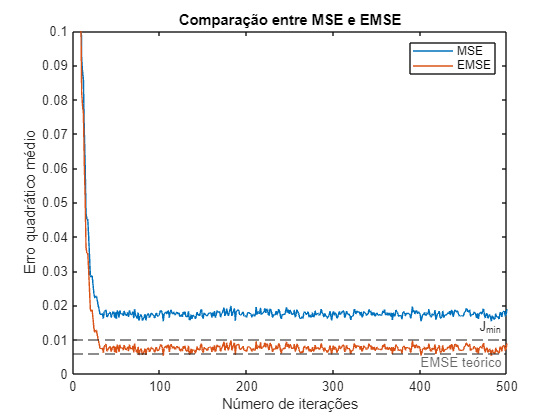


figure;
plot(1:N_iter, mse, 1:N_iter, emse);
yline(J_min, '--', 'J_{min}');
yline(EMSE_teorico, '--', 'EMSE teórico', 'LabelVerticalAlignment', 'bottom');
ylim([0 0.1]);
legend('MSE', 'EMSE');
xlabel('Número de iterações');
ylabel('Erro quadrático médio');
title('Comparação entre MSE e EMSE');

No grafico acima, pode-se verificar o valor do MSE em regime que é de aproximadamente 0.02. O valor teórico do EMSE é de 0.006. 

**f)**

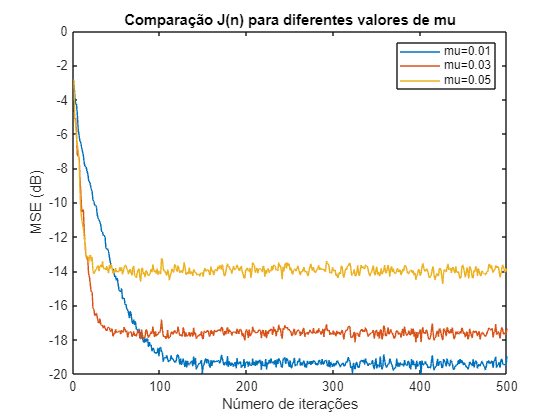

N_monte_carlo = 1000;
mu1 = 0.01;
mu2 = 0.03;
mu3 = 0.05;

erro_med1 = zeros(1, N_iter);
erro_med2 = zeros(1, N_iter);
erro_med3 = zeros(1, N_iter);

for i = 1:N_monte_carlo
    phi_u = 2*pi*rand;
    x = sin(2*pi*n/10 + pi/6 + phi_u);
    u = 5*sin(2*pi*n/10 + phi_u);
    s = sqrt(0.01)*randn(1,N);
    d = s + x;

    [~, erro1] = lms(u, d, M, N_iter, mu1);
    erro_med1 = erro_med1 + erro1 .* erro1;

    [~, erro2] = lms(u, d, M, N_iter, mu2);
    erro_med2 = erro_med2 + erro2 .* erro2;

    [~, erro3] = lms(u, d, M, N_iter, mu3);
    erro_med3 = erro_med3 + erro3 .* erro3;
end
mse1 = 10*log10(erro_med1/N_monte_carlo);
mse2 = 10*log10(erro_med2/N_monte_carlo);
mse3 = 10*log10(erro_med3/N_monte_carlo);

figure;
plot(1:N_iter, mse1, 1:N_iter, mse2, 1:N_iter, mse3);
ylim([-20 0]);
legend('mu=0.01', 'mu=0.03', 'mu=0.05');
title('Comparação J(n) para diferentes valores de mu');
xlabel('Número de iterações');
ylabel('MSE (dB)');

A convergência do modelo é mais rápida para o maior valor de $\mu$=0.05, porém o valor do erro é maior. A convergência mais lenta acontece para   $\mu$=0.01, justificado pela diminuição do tamanho do passo, porém o erro obtido é o menor entre os três, obtendo-se o melhor resultado. Um bom equilibrio entre velocidade e erro acontece para$\mu$=0.03. 